Show how we can add together several shorter exposures -- even with camera motion -- to simulate a single longer exposure

First, set up a default scenario

ieInit;
useScene = 'pavilion-day';
useScenario = ivScenario(useScene);

Now we can modify settings or accept the default, and then create our video clip

sceneVideoClip(useScenario);

[INFO]: Setting integrator to "path" with 5 bounces.
Film diagonal not used for pinhole and human eye
Film diagonal not used for pinhole and human eye
Elapsed time is 0.101018 seconds.
[INFO]: Uploading data:
[INFO]: Sent 2,774 bytes  received 53 bytes  5,654.00 bytes/sec
[INFO]: Data uploaded successfully.
[INFO]: USE Docker: docker  --context remote-orange exec -it  pbrt-gpu-djc18655 sh -c " pbrt  --gpu  --outfile /home/david81/ISETRemoteRender/barcelona-pavilion/renderings/pavilion-day.exr /home/david81/ISETRemoteRender/barcelona-pavilion/pavilion-day.pbrt "
[INFO]: Rendered remotely in: 165.62 sec
[INFO]: Downloading data:
[INFO]: Sent 46 bytes  received 55,259,070 bytes  15,788,318.86 bytes/sec
[INFO]: Data downloaded successfully.
[INFO]: Output file:  renderings/pavilion-day.exr
Elapsed time is 0.116918 seconds.
[INFO]: Uploading data:
[INFO]: Sent 2,781 bytes  received 53 bytes  5,668.00 bytes/sec
[INFO]: Data uploaded successfully.
[INFO]: USE Docker: docker  --context remote-

By default, results are in local/synthetic-scene-tests, labeled with their exposure time in ms,  and the frame number in the multi-frame sequence.

We call sceneSynthesize both on the multiple exposures to sum them up,  and on the longer exposure(s) which we want to compare. 

We do this even for the case of a single longer exposure because it also does some baseline processing of the raw scene.

sceneSynthesize(fullfile(ivDirGet('local'), 'synthetic_scene_tests', [useScene '*016*.exr']),2);
sceneSynthesize(fullfile(ivDirGet('local'), 'synthetic_scene_tests', [useScene '*033*.exr']),1);

NOTE: We need to move the generated files to generated, or put them there right away:)

Now we can compare the synthesized scene(s).

sceneHomeDir = fullfile(ivDirGet('local'), 'synthetic_scene_tests','generated');
[sensor1, sensor2] = sceneCompare(fullfile(sceneHomeDir,[useScene '016-001-002.mat']), ...
    fullfile(sceneHomeDir, [useScene '033-001-001.mat']), .033);

Denoised in: 16.698
Denoised in: 16.233


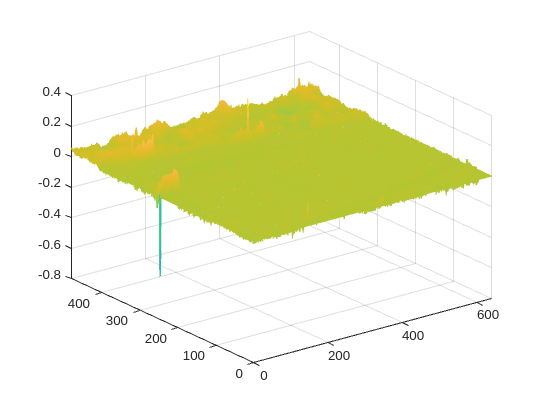

% Show results
mesh(sensor1.data.volts - sensor2.data.volts);

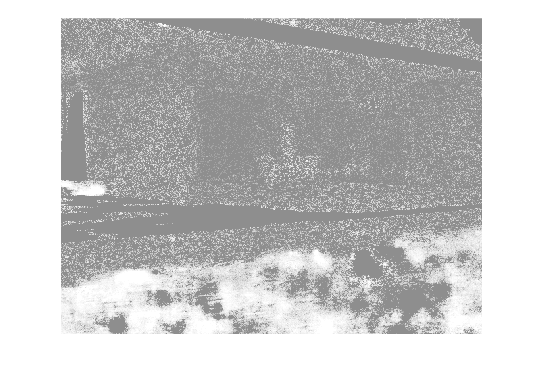


imshow(histeq(sensor1.data.volts - sensor2.data.volts));